# Actividad 3 | Robot cartesiano

Oscar Ortiz Torres A01769292

Yonathan Romero Amador A01737244

Ana Itzel Hernández García A01737526

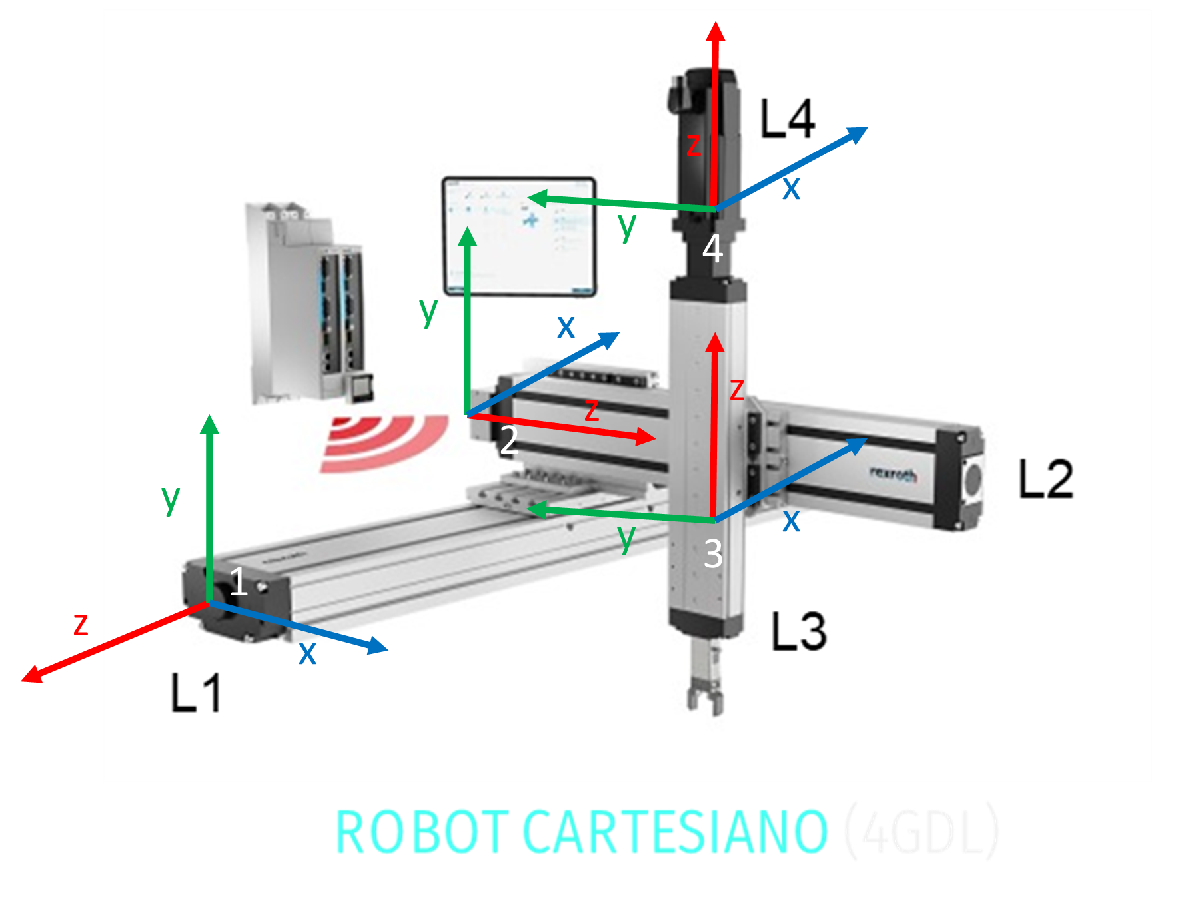

% Limpieza de pantalla
clear all
close all
clc

% Declaración de variables simbolicas
syms l1(t) l2(t) l3(t) l4(t) t

% configuración del robot, 1 para junta prismática
RP = [1 1 1 1];

% Creación del vector de coordenadas articulares
Q = [l1 l2 l3 l4];

% Creación del vector de velocidades generalizadas
Qp = diff(Q, t);

% Número de grados de libertad
GDL = size(RP, 2);
GDL_str = num2str(GDL);

## Articulación 1

% Posición de la articulación 1 respecto a 0
P(:,:,1) = [
            0;
            0;
            l1
           ];

% Matriz de rotación de la junta 1 respecto a la 0
R(:,:,1) = rotY(90)

R =      0     0     1
     0     1     0
    -1     0     0


## Articulacion 2

% Posición de la articulación 2 respecto a 1
P(:,:,2) = [
            0;
            0;
            l2
           ];
% Matriz de rotación de la junta 2 respecto a 1
R(:,:,2) = rotX(-90); R(:,:,2)

ans =      1     0     0
     0     0     1
     0    -1     0


## Articulacion 3

% Posición de la articulación 3 respecto a la 2
P(:,:,3) = [
            0;
            0;
            l3
           ];

% Matriz de rotación de la junta 3 respecto a la 2 (0°)
R(:,:,3) = rotZ(0); R(:,:,3)

ans =      1     0     0
     0     1     0
     0     0     1


## Articulacion 4

% Posición de la articulación 4 respecto a la 3
P(:,:,4) = [
            0;
            0;
            l4
           ];

% Matriz de la rotación de la junta 4 respecto a la  (0°)
R(:,:,4) = rotZ(0); R(:,:,4)

ans =      1     0     0
     0     1     0
     0     0     1


## Matrices

% Creación de vector de ceros
vector_zeros = zeros(1,3);

% Inicialización de las amtrices de Transformación Homogenea locales
A(:, :, GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de las amtrices de transformación Homogenea globales
T(:,:,GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de los vectores de posición vistos desde el marco de
% referencia inercial
PO(:,:,GDL) = P(:,:,GDL);

% Inicialización de las matrices de rotación vistas desde el marco de
% referencia inercial
RO(:,:,GDL) = R(:,:,GDL);

for i = 1:GDL
    i_str = num2str(i);

    % Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([ ...
                         R(:,:,i)       P(:,:,i); ...
                         vector_zeros   1 ...
                        ]); A(:,:,i)

    % Globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i); % Caso específico cuando i=1 nos marcaría error en try
    end

    disp(strcat('Matruz de Transformación global T', i_str));
    T(:,:,i) = simplify(T(:,:,i)); T(:,:,i)

    % Obtención de la matriz de rotación "RO" y el vector de traslación PO
    % de la matriz de transformación homogenea global T(:,:, GDL)
    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
end

Matriz de Transformación local A1


$$ans = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T1


$$ans = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A2


$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T2


$$ans = \left(\begin{array}{cccc} 0 & -1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 1 & 0\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A3


$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T3


$$ans = \left(\begin{array}{cccc} 0 & -1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A4


$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{4}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T4


$$ans = \left(\begin{array}{cccc} 0 & -1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 1 & l_{3}\left(t\right)+l_{4}\left(t\right)\\ -1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Jacobiano lineal y angular de forma analítica

% Inicialización de jacobianos analíticos
Jv_a(:,GDL) = PO(:,:,GDL); % Lineal 
Jw_a(:,GDL) = PO(:,:,GDL); % Angular

for k = 1:GDL
    if(RP(k) == 0)
        % Para las articulaciones rotacionales
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0 0 1], PO(:,:,GDL)); % Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k) = [0 0 1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
    elseif(RP(k) == 1)
        % Para las articulaciones prismáticas
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0,0,1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
            Jw_a(:,k) = [0 0 0];
    end
end


## Despliegue

disp('Jacobiano lineal obtenido de forma analítica'); Jv_a = simplify(Jv_a)

Jacobiano lineal obtenido de forma analítica


$$Jv\_a = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 1\\ 1 & 0 & 0 & 0 \end{array}\right)$$

disp('Jacobiano angular obtenido de forma ananlítica'); Jw_a = simplify(Jw_a)

Jacobiano angular obtenido de forma ananlítica


$$Jw\_a = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); V = simplify(Jv_a * Qp')

Velocidad lineal obtenida mediante el Jacobiano lineal


$$V(t) = \left(\begin{array}{c} \bar{\frac{\partial }{\partial t}l_{2}\left(t\right)}\\ \bar{\frac{\partial }{\partial t}l_{3}\left(t\right)}+\bar{\frac{\partial }{\partial t}l_{4}\left(t\right)}\\ \bar{\frac{\partial }{\partial t}l_{1}\left(t\right)} \end{array}\right)$$

disp('Velocidad angular obtenida mediante el Jacobiano angular'); W = simplify(Jw_a * Qp')

Velocidad angular obtenida mediante el Jacobiano angular


$$W(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

## Funciones de rotacion

function r_x = rotX(th)
    r_x = [1 0 0; 0 cosd(th) -sind(th); 0 sind(th) cosd(th)];
end

function r_y = rotY(th)
    r_y = [cosd(th) 0 sind(th); 0 1 0; -sind(th) 0 cosd(th)];
end

function r_z = rotZ(th)
    r_z = [cosd(th) -sind(th) 0; sind(th) cosd(th) 0; 0 0 1];
end